## Navigation Ability = 1

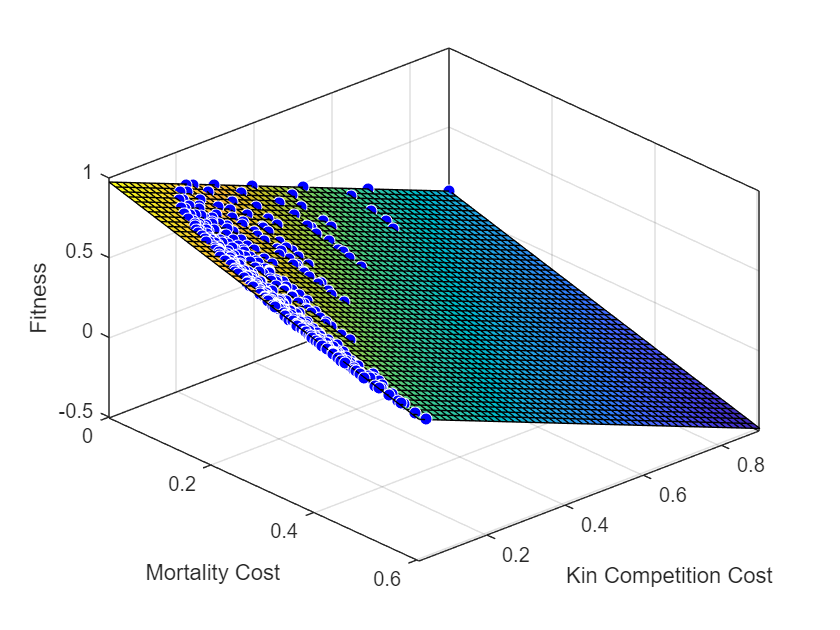

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_1\fitness_surface.mat')

all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
%% 3D surface: mort and kin comp vs fitness
f = fit([out_mortcost out_kincost],out_fitness,"poly11");
plot(f,[out_mortcost out_kincost],out_fitness)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([47.70 39.15])

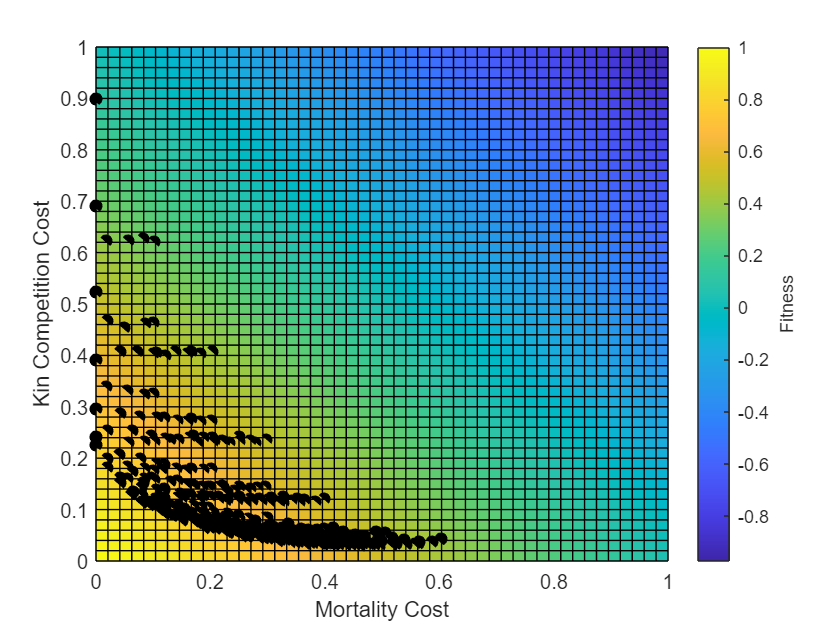


figure
clf
hold on
plot(f)
plot3(out_mortcost, out_kincost,out_fitness,'ok','MarkerFaceColor','k')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([0 90])
a = colorbar;
a.Label.String = 'Fitness';
hold off

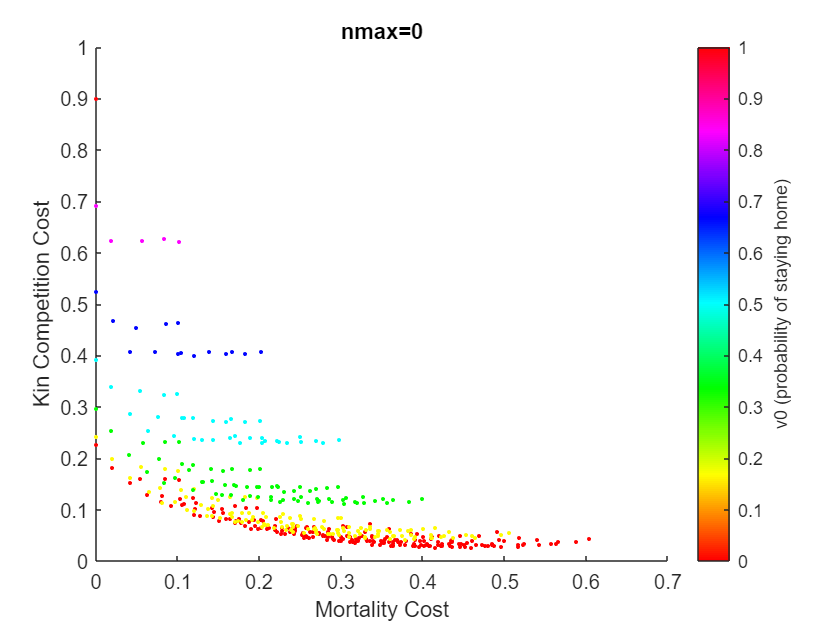

% scatterplot, with bands identified as constant v0
figure
scatter(all,'Mortality','KinComp','ColorVariable','v0','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'v0 (probability of staying home)';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')

## Navigation Ability = 2

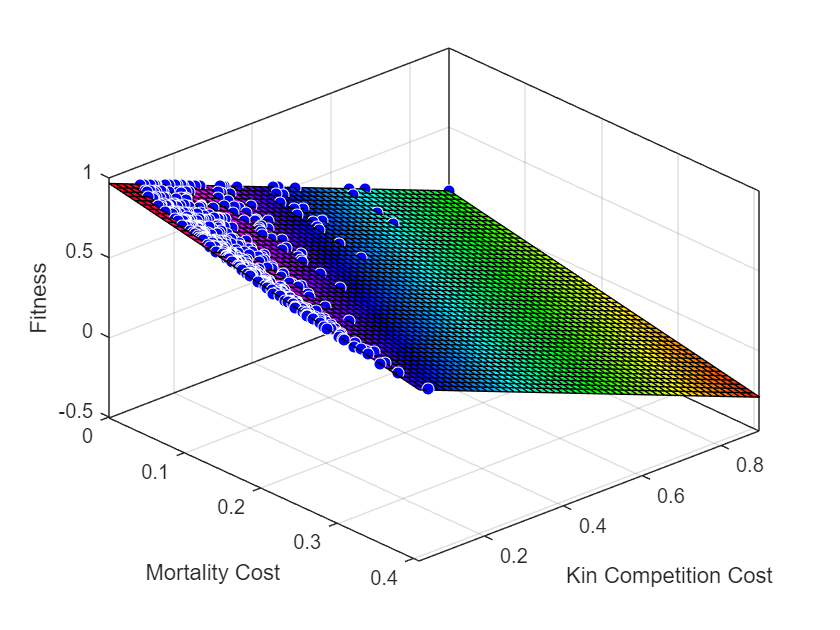

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_2\fitness_surface.mat')

all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
%% 3D surface: mort and kin comp vs fitness
f = fit([out_mortcost out_kincost],out_fitness,"poly11");
plot(f,[out_mortcost out_kincost],out_fitness)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([47.70 39.15])

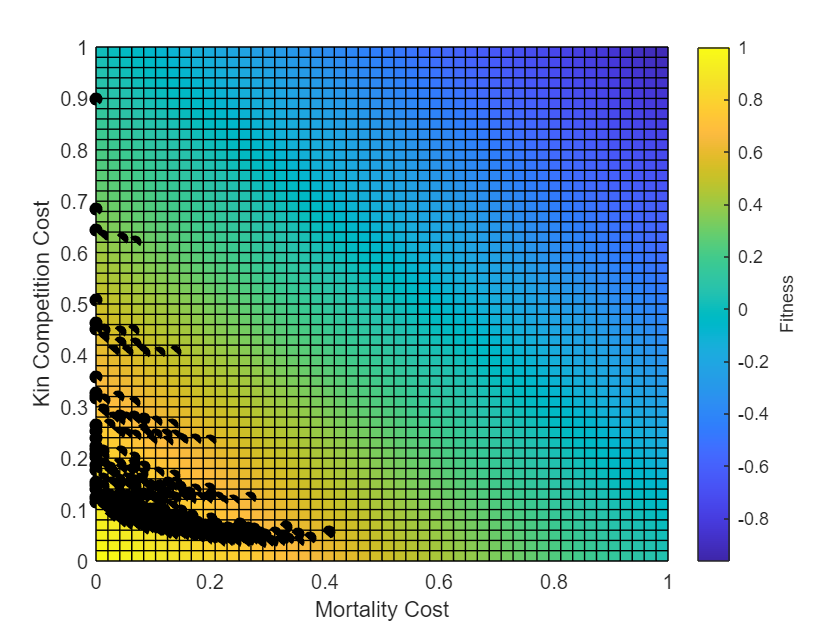


figure
clf
hold on
plot(f)
plot3(out_mortcost, out_kincost,out_fitness,'ok','MarkerFaceColor','k')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([0 90])
a = colorbar;
a.Label.String = 'Fitness';
hold off

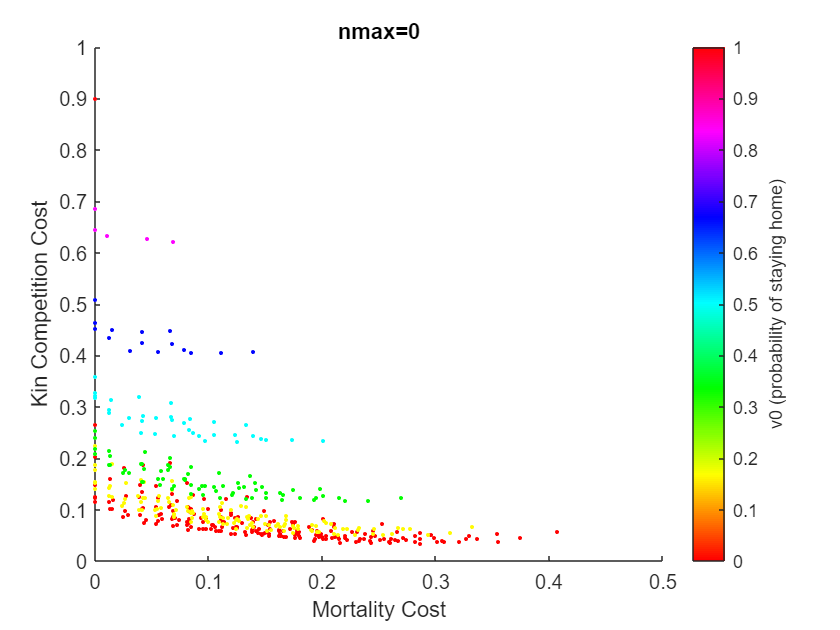

% scatterplot, with bands identified as constant v0
figure
scatter(all,'Mortality','KinComp','ColorVariable','v0','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'v0 (probability of staying home)';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')